# Multi-Target ML Pipeline - Robust MATLAB Version

rng(42); % reproducibility

## Parameters

nSamplesDefault = 500; % default sample size if synthetic
nPhyto = 5; nOmics = 5; nNano = 5;

## Load CSV if available

datasetLoaded = false;
fileList = { ...
    'synthetic_anticancer_dataset_for_pipeline.csv', ...
    'synthetic_anticancer_dataset_grouped_v2.csv', ...
    'synthetic_anticancer_dataset_grouped.csv', ...
    'synthetic_anticancer_dataset.csv', ...
    'synthetic_anticancer_dataset_1000_samples.csv'};
for f = 1:numel(fileList)
    if isfile(fileList{f})
        disp(['Loading dataset: ' fileList{f}]);
        T = readtable(fileList{f});
        datasetLoaded = true;
        break;
    end
end

Loading dataset: synthetic_anticancer_dataset_1000_samples.csv


## Detect numeric features and targets robustly

X = []; featureNames = {}; yClassMat = []; yRegMat = [];
if datasetLoaded
    numericCols = varfun(@isnumeric, T, 'OutputFormat', 'uniform');
    Xtemp = T(:, numericCols);

    % Assume last 2 numeric columns are regression targets if >2 numeric cols
    if width(Xtemp) > 2
        X = Xtemp(:, 1:end-2);
        yRegMat = table2array(Xtemp(:, end-1:end));
    elseif width(Xtemp) > 0
        X = Xtemp;
    end

    % Check for binary classification target (0/1 or -1/1)
    for c = 1:width(Xtemp)
        uniqVals = unique(Xtemp{:,c});
        if numel(uniqVals) == 2
            yClassMat = Xtemp{:,c};
            X(:,c) = [];
        end
    end

    featureNames = X.Properties.VariableNames;
    X = table2array(X); % convert to numeric matrix
end

## Synthetic fallback if no valid features or targets

if isempty(X)
    disp('Generating bulletproof synthetic dataset...');
    nSamples = nSamplesDefault;
    Phytochem = randn(nSamples,nPhyto); 
    Omics     = randn(nSamples,nOmics); 
    Nano      = randn(nSamples,nNano);

    X = [Phytochem Omics Nano];
    featureNames = [strcat("Phyto",string(1:nPhyto)), ...
                    strcat("Omics",string(1:nOmics)), ...
                    strcat("Nano",string(1:nNano))];

    sumPhyto = sum(Phytochem,2); sumOmics = sum(Omics,2); sumNano  = sum(Nano,2);

    % Classification target
    yClassMat = sumPhyto + 0.5*sumOmics + 0.3*sumNano + randn(nSamples,1);
    yClassMat = double(yClassMat>0); yClassMat(yClassMat==0) = -1;

    % Regression targets
    yRegMat = [0.8*sumPhyto - 0.4*sumOmics + 0.6*sumNano + randn(nSamples,1), ...
               0.5*sumPhyto + 0.2*sumOmics + 0.4*sumNano + randn(nSamples,1)];
else
    nSamples = size(X,1); % auto-detect sample count
end
disp(['Detected number of samples: ', num2str(nSamples)]);

Detected number of samples: 1000


## Convert classification targets to categorical

if ~isempty(yClassMat)
    yClassMat = categorical(string(yClassMat));
end

## Train/Test Split

if nSamples <= 1
    warning('X has too few rows; using full dataset for training/testing.');
    trainIdx = 1:nSamples; testIdx = 1:nSamples;
else
    cv = cvpartition(nSamples,'Holdout',0.3);
    trainIdx = training(cv); testIdx = test(cv);
end
Xtrain = X(trainIdx,:); Xtest = X(testIdx,:);

## ---------------- Classification ----------------

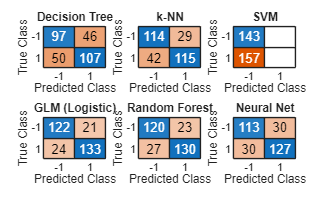

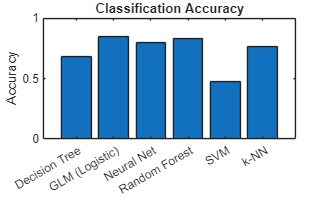

if ~isempty(yClassMat)
    classModelList = {
        'Decision Tree', @(X,Y) fitctree(X,Y)
        'k-NN', @(X,Y) fitcknn(X,Y,'NumNeighbors',5)
        'SVM', @(X,Y) fitcsvm(X,Y,'KernelFunction','rbf','Standardize',true)
        'GLM (Logistic)', @(X,Y) fitclinear(X,Y,'Learner','logistic')
        'Random Forest', @(X,Y) fitcensemble(X,Y,'Method','Bag')
        'Neural Net', @(X,Y) fitcnet(X,Y)
        };

    nClassModels = size(classModelList,1); % auto-detect bounds
    classAccTable = zeros(1,nClassModels);

    figure('Name','Confusion Matrices: Classification'); 
    tiledlayout(2,3,'TileSpacing','compact');

    yCtrain = yClassMat(trainIdx);
    yCtest  = yClassMat(testIdx);

    for i = 1:nClassModels
        mdl = classModelList{i,2}(Xtrain, yCtrain);
        ypred = predict(mdl, Xtest);

        acc = mean(ypred == yCtest);
        classAccTable(i) = acc;

        nexttile; confusionchart(yCtest, ypred); title(classModelList{i,1});
    end

    figure; bar(categorical(classModelList(:,1)), classAccTable); 
    ylabel('Accuracy'); title('Classification Accuracy');
end

## ---------------- Regression ----------------

if ~isempty(yRegMat)
    regModelList = {
        'Linear Regression', @(X,Y) fitlm(X,Y)
        'SVM Regression', @(X,Y) fitrsvm(X,Y,'KernelFunction','rbf','Standardize',true)
        'Random Forest', @(X,Y) fitrensemble(X,Y,'Method','Bag')
        'GLM Regression', @(X,Y) fitglm(X,Y)
        };

    nRegModels = size(regModelList,1); % auto-detect bounds
    nRegTargets = size(yRegMat,2);
    regRmseTable = zeros(nRegTargets,nRegModels);

    for t = 1:nRegTargets
        yRtrain = yRegMat(trainIdx,t); yRtest = yRegMat(testIdx,t);
        rmse = zeros(1,nRegModels);
        for i = 1:nRegModels
            mdl = regModelList{i,2}(Xtrain, yRtrain);
            ypred = predict(mdl, Xtest);
            rmse(i) = sqrt(mean((yRtest - ypred).^2));
        end
        regRmseTable(t,:) = rmse;
    end
end

## ---------------- Combined Dashboard ----------------

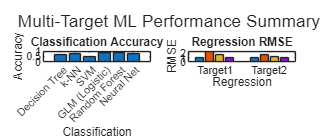

figure('Name','ML Performance Summary','Position',[100 100 1200 500]);
tiledlayout(1,2,'TileSpacing','compact');

if exist('classAccTable','var') && ~isempty(classAccTable)
    nexttile(1); bar(classAccTable);
    set(gca,'XTickLabel', classModelList(:,1));
    ylabel('Accuracy'); xlabel('Classification'); title('Classification Accuracy');
end
if exist('regRmseTable','var') && ~isempty(regRmseTable)
    nexttile(2); bar(regRmseTable);
    set(gca,'XTickLabel', strcat("Target",string(1:nRegTargets)));
    ylabel('RMSE'); xlabel('Regression'); title('Regression RMSE');
end

sgtitle('Multi-Target ML Performance Summary');